# **Simulationstechnik Programmentwurf**

## Aufgabe 1

## Das nicht-lineare Einspurmodell

Das System ist ein nicht-lineares Einspurmodell, beschrieben durch ein Differentialgleichungssystem der Änderungen des Schwimmwinkels und der Giergeschwindigkeit folgender Form: 


$$\dot{\beta}= -\dot{\psi} + \frac{1}{m\cdot v} \cdot (c_v \alpha_v(\beta, \dot{\psi}) \frac{\cos(\delta)}{\cos(\beta)}+ c_h  \alpha_h(\beta, \dot{\psi}) \frac{1}{\cos(\beta)}) \\

 \ddot{\psi} = \frac{1}{J} \cdot (c_v \alpha_v(\beta) l_v \cos(\delta) + c_h \alpha_h(\beta) l_h)
    \end{bmatrix}$$


#### Gleichungen der Schräglaufwinkeln


$$    \alpha_v(\beta, \dot{\psi}) = \delta - \frac{l_v\cdot \dot{\psi}}{v\cdot \cos(\beta)} + \tan{\beta} 

$$



$$    \alpha_h(\beta, \dot{\psi}) = - \frac{l_h\cdot \dot{\psi}}{v\cdot \cos(\beta)} - \tan{\beta}
$$


#### System Paramtern

- massen $m
$... $kg
$

-  Massenträgheitsmoment $J
$...$kg\cdot m^2$

- Länge des Fahrzeugs $l_v...m$ $l_h...m
$

- Schräglaufwinkel$c_v...\frac{N}{rad}$

- Betrag der Geschwindigkeit des Fahrzeugs... $v$

m = 2000; %kg masse vom KFZ
J = 4000;  %kgm^2 massenträgheitsmoment
l_v = 1.43; %m  länge vorne 
l_h = 1.4; %m länge hinten

%Schräglaufkoeffizienten
c_v = 70000; % N/rad 
c_h = 140000; % N/rad 

delta = 5 *  pi /180; % rad
v = 18; %m/s
alpha_v = @(beta, psi_dot) delta - (l_v * psi_dot / (v* cos(beta))) + tan(beta);
alpha_h = @(beta, psi_dot)  (l_h * psi_dot / (v* cos(beta))) - tan(beta);



#### Zustandvektor des Systems


$$\;Y=\left\lbrack \begin{array}{c}
\beta \\
\dot{\psi} 
\end{array}\right\rbrack$$
  
$$\dot{\dot{Y} =\left\lbrack \begin{array}{c}
\dot{\beta} \\
\ddot{\psi} 
\end{array}\right\rbrack }$$


Beide Differentialgleichungen im System sind Differentialgleichungen 1.Ordnung. Damit ist die Aufstellung des Zustandsvektors in Matlab sehr einfach. In der Form kann das System in Matlab schon numerisch gelöst mit sämtlichen Solvern. 


t = [0 10]; % Zeitvektor in s

%beta_dot
f_1  = @( beta, psi_dot) (-1)*psi_dot + (1/(m*v)*(c_v * alpha_v(beta, psi_dot)* (cos(delta)/cos(beta)) + c_h * alpha_h(beta, psi_dot)* (1/cos(beta))));
%psi_ddot
f_2 = @(beta, psi_dot) (1/J)*(l_v * c_v * alpha_v(beta, psi_dot) * cos(delta) - l_h * c_h * alpha_h(beta, psi_dot));

%Y
f = @(t, Y) [f_1(Y(1), Y(2)); f_2(Y(1),Y(2))];


#### Lösung mit ode45

oder45 eignet sich für die bestimmte Aufgabe. Das System ist glatt und wenig steif heirfür eignet sich das oder45 von Matlab. 

%optimierungseinstellungen
opts = odeset( ...
    'RelTol', 1e-6, ...
    'AbsTol', [1e-9 1e-9], ...   % AbsTol pro Zustand (beta, psi_dot)
    'MaxStep', 0.01, ...         % maximale Schrittweite
    'InitialStep', 1e-3, ...     % Anfangsschrittweite
    'Stats','on' );

% numerische Lösung 
[t_nonlin_ss, x_nonlin_ss] = ode45(f, t, [0; 0], opts);

1002 successful steps
0 failed attempts
6013 function evaluations


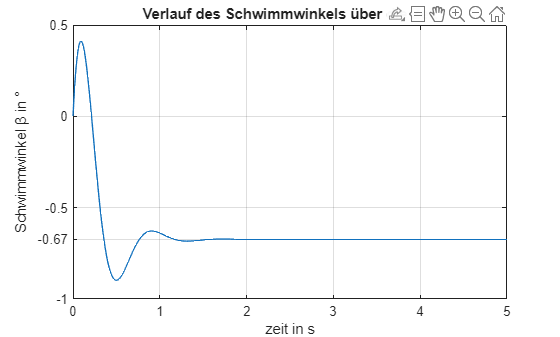


% time series werte von beta 
beta_nonlin_ss = x_nonlin_ss(:,1);
% time series werte von psi
psi_dot_nonlin_ss = x_nonlin_ss(:,2);

% Endwerten
beta_ss_deg = beta_nonlin_ss(end)* 180/pi;
psi_dot_ss = psi_dot_nonlin_ss(end) * 180/pi;

% plot beta
figure; plot(t_nonlin_ss, beta_nonlin_ss * 180/pi, '-')
addAsymptTick(beta_ss_deg)
xlim([0 5])
grid on, 
xlabel('zeit in s'), ylabel('Schwimmwinkel β in °')
title("Verlauf des Schwimmwinkels über die Zeit")

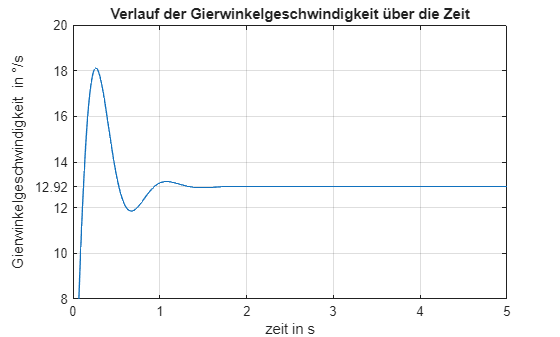


% plot psi
figure; plot(t_nonlin_ss, psi_dot_nonlin_ss * 180 /pi, '-')
ylim([8 20])
xlim([0 5])

addAsymptTick(psi_dot_ss)
grid on,
xlabel('zeit in s'), ylabel('Gierwinkelgeschwindigkeit  in °/s')
title("Verlauf der Gierwinkelgeschwindigkeit über die Zeit")


fprintf("beta* = %f °", beta_ss) 

beta* = -0.673705 °

fprintf("psi_dot* = %f °/s", psi_dot_ss) 

psi_dot* = 12.921122 °/s


function addAsymptTick(asympt)
    yt = yticks;
    yt = sort([yt asympt]);   
    yticks(yt)
    yl = string(yt); %labels
    %logischen Index
    idx = abs(yt - asympt) < 1e-6;
    yl(idx) = sprintf(" %.2f", asympt);
    
    yticklabels(yl)
end

## Aufgabe 4

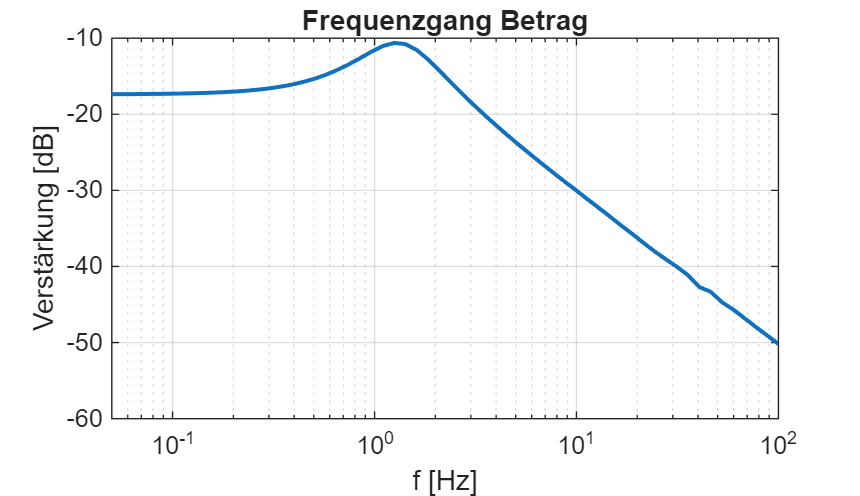

%% Frequenzgang des linearen Einspurmodells (0.05 Hz – 100 Hz) – gleiche Plotgröße, exakter Bereich

mdl = "linear_Einspurmodel";
load_system(mdl);

% Fahrzeuggeschwindigkeit
v = 18;
assignin("base","v",v);

A = 1; % Lenkwinkelamplitude [deg]

% Frequenzbereich in Hz (exakt)
f_min = 0.05;
f_max = 100;
f = logspace(log10(f_min), log10(f_max), 60);
w = 2*pi*f;  % rad/s

mag   = zeros(size(f));
phase = zeros(size(f));

for k = 1:length(w)
    wk = w(k);
    T  = 2*pi/wk;

    % Simulationszeit (mehrere Perioden)
    t_end = 12*T;
    t = linspace(0, t_end, 4000)';

    % Sinuslenkung
    u = A*sin(wk*t);
    u_ext = [t u];

    % Simulation
    simIn = Simulink.SimulationInput(mdl);
    simIn = simIn.setVariable("u_ext", u_ext);
    simIn = simIn.setVariable("v", v);
    simIn = simIn.setModelParameter( ...
        "LoadExternalInput","on", ...
        "ExternalInput","u_ext", ...
        "StopTime", num2str(t_end), ...
        "SignalLogging","on", ...
        "SignalLoggingName","logsout");

    simOut = sim(simIn);

    % Output beta
    beta_ts = simOut.logsout.getElement("beta").Values;
    y = beta_ts.Data;
    t = beta_ts.Time;

    % stationären Bereich auswerten
    idx = t > 6*T;
    t = t(idx);
    y = y(idx);

    % Sinusfit -> Betrag & Phase
    S = sin(wk*t);
    C = cos(wk*t);
    p = [S C]\y;

    A_out = hypot(p(1), p(2));
    phi   = atan2(p(2), p(1));

    mag(k)   = 20*log10(A_out/A);
    phase(k) = rad2deg(phi);
end

%% Plot-Layout (beide Figuren exakt gleich groß)
figPos = [100 100 900 520];   % [x y breite höhe] – beliebig, aber gleich für beide

% Verstärkung
figure('Position', figPos);
semilogx(f, mag, 'LineWidth', 1.5);
grid on;
xlim([f_min f_max]);          % Bereich exakt 0.05..100 Hz
xlabel('f [Hz]');
ylabel('Verstärkung [dB]');
title('Frequenzgang Betrag');

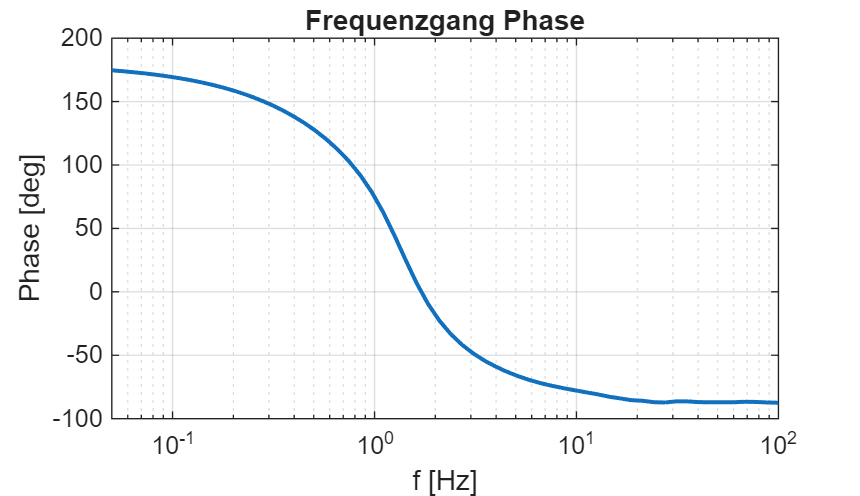


% Phase
figure('Position', figPos);
semilogx(f, phase, 'LineWidth', 1.5);
grid on;
xlim([f_min f_max]);          % Bereich exakt 0.05..100 Hz
xlabel('f [Hz]');
ylabel('Phase [deg]');
title('Frequenzgang Phase');

## Aufgabe 5

### Bestimmung der optimalen Geschwindigkeit

Ziel der Aufgabe ist es, eine Geschwindigkeit $v^*
$zu bestimmen, bei der der stationäre Schwimmwinkel $\beta_{ss}$ möglichst klein wird. Der stationäre Wert $\beta_{ss}$ ergibt sich dabei als Grenzwert des zeitabhängigen Schwimmwinkels $\beta(t)$für $t \rightarrow \infty$. In der Simulation wird dieser stationäre Zustand approximiert, indem der Mittelwert des Schwimmwinkels in der letzten Sekunde der Simulation betrachtet wird.

Die optimale Geschwindigkeit wird anschließend durch Minimierung des Betrags des stationären Schwimmwinkels bestimmt


$$
v^* = \arg \min_v |\beta_{ss}(v)|
$$


sodass für die optimale Geschwindigkeit näherungsweise $\beta_{ss}(v^*) \approx 0 $ gilt. Die Bestimmung erfolgt numerisch durch wiederholte Simulation des Einspurmodells für unterschiedliche Geschwindigkeiten. In Matlab eignet sich hierfür der Solver fminbnd für ein Dimensionale Funktionen. 

#### Das Laden des linearen Spurmodells 

Das Simulink Modell für das lineares Einspurmodell wird über die Funktion "load_system" geladen. 

% füge den verzeichnis zu path damit sichergestellt wird, dass mdl gefunden
% wird 
addpath(pwd)

mdl = "linear_Einspurmodel";
if ~bdIsLoaded(mdl)
    load_system(mdl)
end

### Simulationsparametern

Der Eingangsvektotr in_ext wird über den set_param übergeben, als alle input  des Oberen Operationsschicht des Simulinks

t = (0:0.01:10)';                 
delta = 5 * ones(size(t));  

% eingangsvektor
in_ext = [t delta];                    
v = 18

v = 18

### Setze die Paramtern für alle In Blocks im Simulink Model

set_param(mdl,'LoadExternalInput','on');
set_param(mdl,'ExternalInput','in_ext');
simOut = sim(mdl,'StopTime','10');

### Logged Signale werden nach der Simulation gelesen

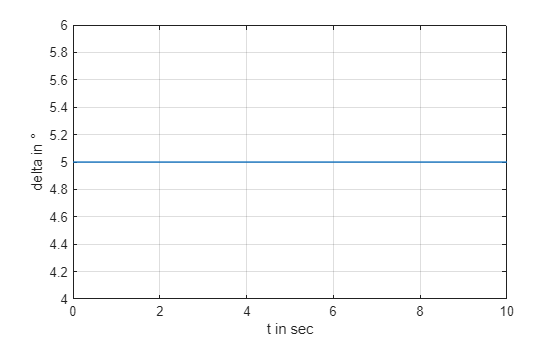


%logged Signale in Simulink
beta_ts   = simOut.logsout.getElement('beta').Values;
delta_ts = simOut.logsout.getElement('delta_in').Values;

%test plot für Konsistenz mit vorherigen Aufgaben
figure; plot(delta_ts.Time, delta_ts.Data); 
grid on
ylabel("delta in °")
xlabel("t in sec")

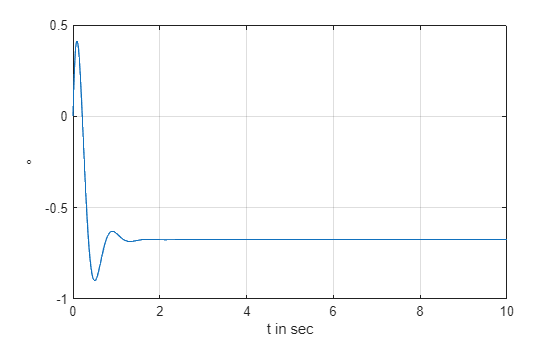

figure;
plot(beta_ts.Time, beta_ts.Data)
grid on
ylabel("°")
xlabel("t in sec")

### Die Güte Funktion 

Der Optimierungssolver fminbnd bestimmt das lokale Minima in einem lokalen Interval. Dieser lokalen Interval wird angegeben, als der realistisch realsierbare Geschwindigkeit vom Fahrzeug. 

Nach Definition der optimalen Geschwindigkeit wie oben erklärt wird bei der Optimierung nicht das Minimum sondern die Nullstelle der Funktion gesucht. Hierfür verwendet man den Solver fminbnd mit dem Quadrat der Funktion, da der Solver eigentlich das Minima in einem Interval sucht, kann man die Bestimmung der Nulltstelle in eine Bestimmung eines Minimas transferieren, indem man die Gütefunktion als Quadrat der Ausgangsfunktion bzw den Betrag. 

% güte Funktion von beta(v)
cost_beta = @(v) beta(v)^2;

% beta aus dem Simulationsmodell bestimmen 
function J = beta(v)
    mdl = "linear_Einspurmodel";
    assignin('base','v',v);

    % simuliere mit einer Zeitspanne von 10 sec
    simOut = sim(mdl,'StopTime','10');

    %die werten der Simulation in der letzten Sekunde
    %da wir 0de45 einsetzen, verweden wir einen logischen index
    beta_ts = simOut.logsout.getElement('beta').Values;
    idx = beta_ts.Time >= beta_ts.Time(end)-1;

    %nehme den durchschnitt der werten der letzten sekunde
    beta_ss = mean(beta_ts.Data(idx));
     
    J = beta_ss;
end

#### Optimierung mit fminbnd

fminbnd ist ein solver, Minima von ein dimensionalen Funktionen numerisch in einem gegebene Interval bestimmen kann. 

v_min = 0;
v_max = 50;

[v_opt, J_opt] = fminbnd(cost_beta, v_min, v_max);

disp("Optimale Geschwindigkeit:")

Optimale Geschwindigkeit:


fprintf("%.2f m/s", v_opt)

13.93 m/s

disp("Minimaler Wert von beta_ss:")

Minimaler Wert von beta_ss:


fprintf("%.2f °", J_opt)

0.00 °

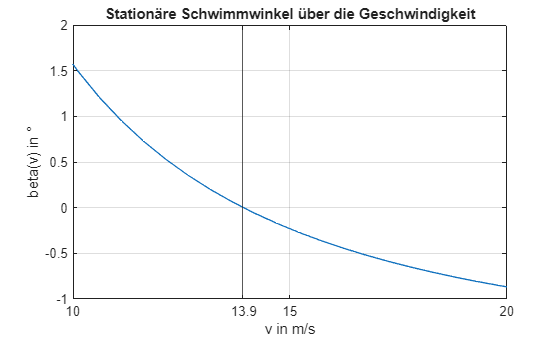

v_test = linspace(5,30,50);
b = zeros(size(v_test));

for i = 1:length(v_test)
    b(i) = beta(v_test(i));
end

plot(v_test, b)
xt = xticks;
xt = sort([xt 13.9]);   
xticks(xt)
xl = string(xt); %labels
%logischen Index
idx = abs(xt - 13.9) < 1e-6;
xl(idx) = sprintf(" %.1f", 13.9);

xticklabels(xl)
xline(13.9)
xlim([10 20])
grid on
title("Stationäre Schwimmwinkel über die Geschwindigkeit")
xlabel('v in m/s')
ylabel('beta(v) in °')